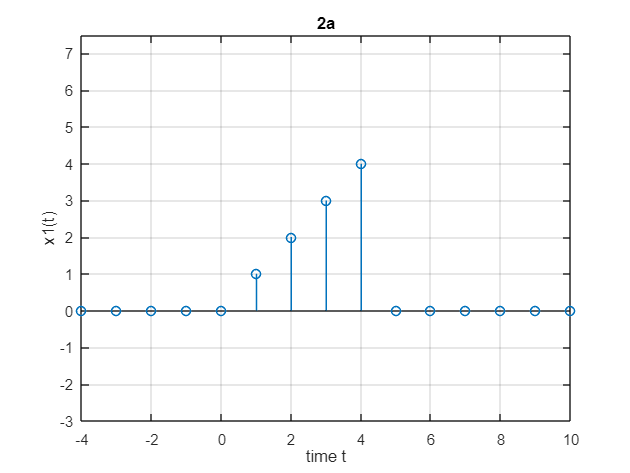

% Problem 1

% 1
t = -40:1:40; % Time values from -5 to 5 with a step of 0.01

% Create the unit step function
u = @(a) (a>=0);
d = @(a) (a==0);

x1 = @(b) b.*(u(b) - u(b-5));
x2 = @(b) 4*(u(b-5) - u(b-11));
x3 = @(b) -2*d(b-8);

x = @(b) x1(b)+x2(b)+x3(b);

% 2
stem(t,x1(t),'LineWidth',1)
ylim([-3 7.50])
xlim([-4.00 10.00])
title('2a');
ylabel('x1(t)')
xlabel('time t')
grid on

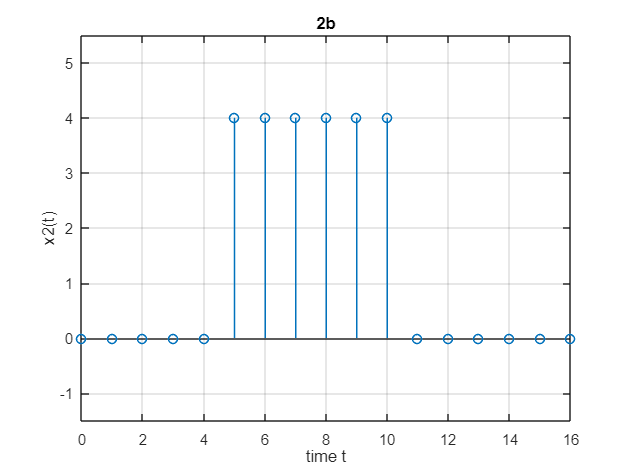


stem(t,x2(t),'LineWidth',1)
ylim([-1.5 5.5])
xlim([0.00 16.00])
title('2b');
ylabel('x2(t)')
xlabel('time t')
grid on

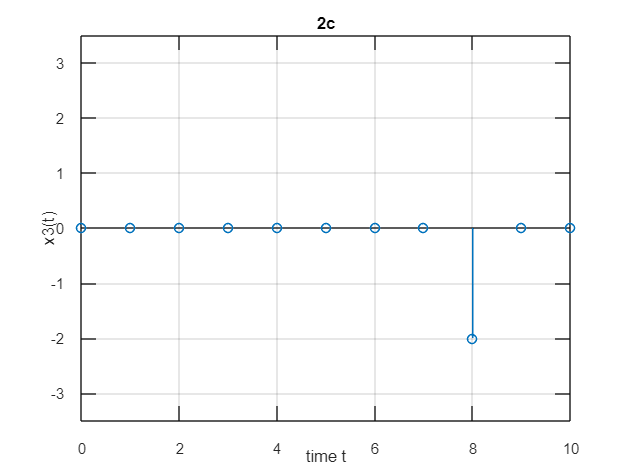


stem(t,x3(t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([0.00 10.00])
title('2c');
ylabel('x3(t)')
xlabel('time t')
grid on

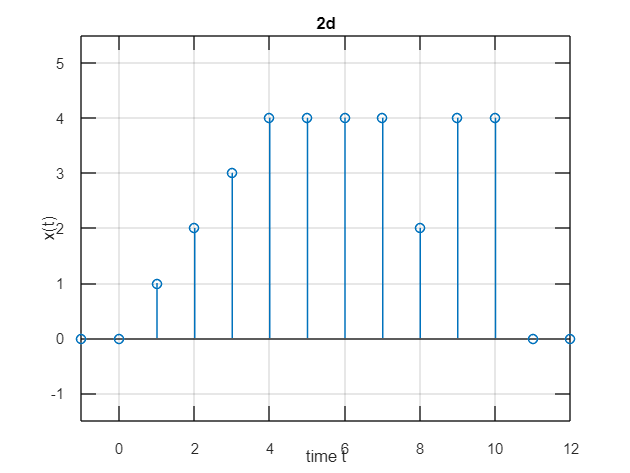


stem(t,x(t),'LineWidth',1)
ylim([-1.5 5.5])
xlim([-1.00 12.00])
title('2d');
ylabel('x(t)')
xlabel('time t')
grid on

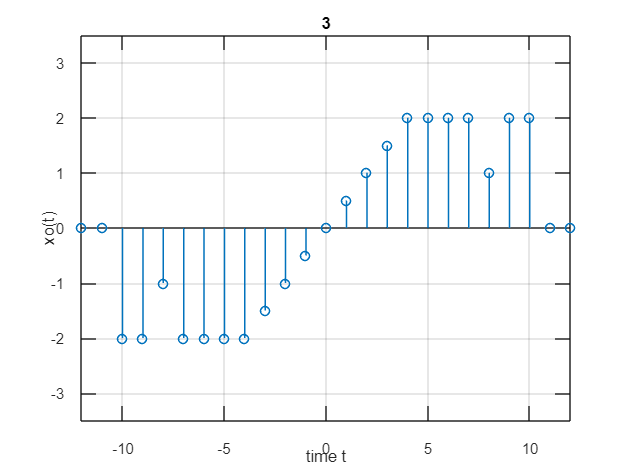


% 3
stem(t,odd(x, t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-12.00 12.00])
title('3');
ylabel('xo(t)')
xlabel('time t')
grid on

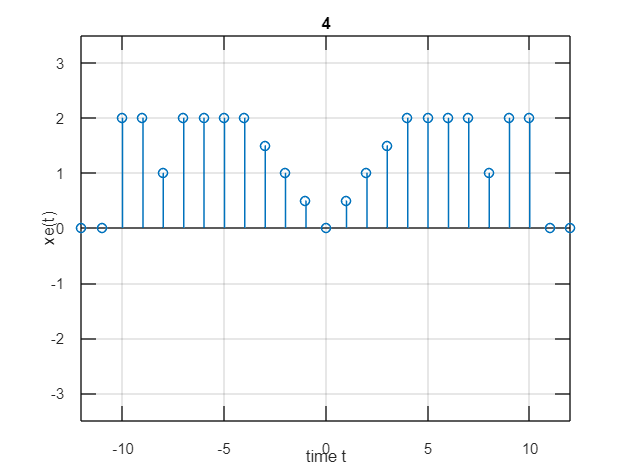


% 4
stem(t,even(x, t),'LineWidth',1)
ylim([-3.5 3.5])
xlim([-12.00 12.00])
title('4');
ylabel('xe(t)')
xlabel('time t')
grid on


% 5
totalEnergy = sum(abs(x(t)).^2)

totalEnergy = 114


% 6
oddEnergy = sum(abs(odd(x, t)).^2)

oddEnergy = 57

evenEnergy = sum(abs(even(x, t)).^2)

evenEnergy = 57

oddEnergy + evenEnergy

ans = 114

% oddEnergy + evenEnergy = totalEnergy


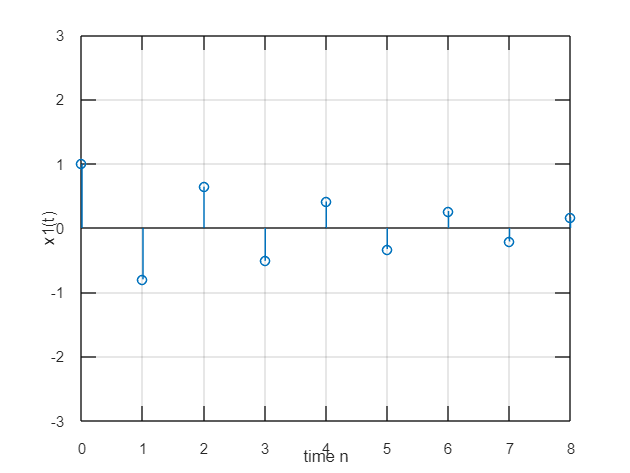

% Problem 2

t = 0:8;

x1 = @(b) (-0.8).^b;
x2 = @(b) (0.5).^b;
x3 = @(b) (1.1).^b;

stem(t,x1(t),'LineWidth',1)
ylim([-3 3])
xlim([0.00 8.00])
ylabel('x1(t)')
xlabel('time n')
grid on

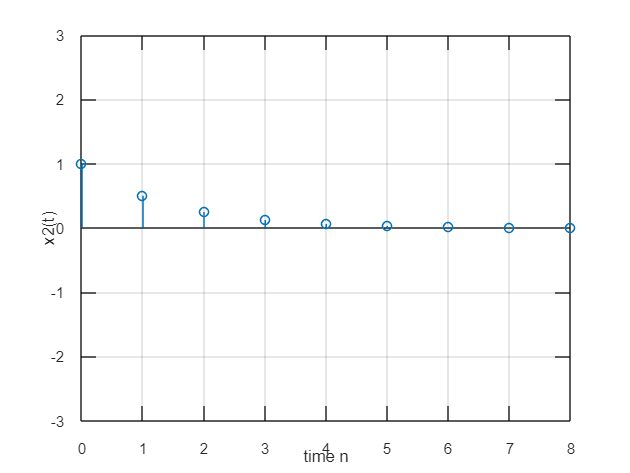


stem(t,x2(t),'LineWidth',1)
ylim([-3 3])
xlim([0.00 8.00])
ylabel('x2(t)')
xlabel('time n')
grid on

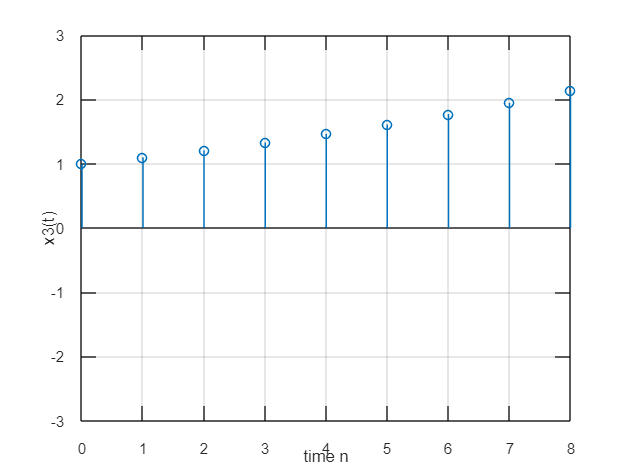


stem(t,x3(t),'LineWidth',1)
ylim([-3 3])
xlim([0.00 8.00])
ylabel('x3(t)')
xlabel('time n')
grid on

function comp = odd(funct, in) % ang must be in rad; returns in rad
    comp = (funct(in)-funct(-in))/2;
end

function comp = even(funct, in) % ang must be in rad; returns in rad
    comp = (funct(in)+funct(-in))/2;
end